# Turkish Exam Question

clear all
addpath ../
latex_interpreter
xval = [1 2 3 1 3];
y = [1 4 3 0 0];

syms x P(x) dPdx(x) a b c d e
P(x) = poly2sym([a b c d e], x)

$$P(x) = a\,x^{4}+b\,x^{3}+c\,x^{2}+d\,x+e$$

dPdx(x) = diff(P(x))

$$dPdx(x) = 4\,a\,x^{3}+3\,b\,x^{2}+2\,c\,x+d$$


expr = [P(1); P(2); P(3); dPdx(1); dPdx(3)] == y'

$$expr = \left(\begin{array}{c} a+b+c+d+e=1\\ 16\,a+8\,b+4\,c+2\,d+e=4\\ 81\,a+27\,b+9\,c+3\,d+e=3\\ 4\,a+3\,b+2\,c+d=0\\ 108\,a+27\,b+6\,c+d=0 \end{array}\right)$$

soln = vpasolve(expr)

soln = struct with fields:
    a: 2.0
    b: -16.5
    c: 47.0
    d: -52.5
    e: 21.0


expressionMine = subs(P(x), soln)

$$expressionMine = 2.0\,x^{4}-16.5\,x^{3}+47.0\,x^{2}-52.5\,x+21.0$$

answerMine = subs(P(4), soln)

$$answerMine = 19.0$$


expressionHers = expand(2*(x-1)^2*(x-3)^2+x)

$$expressionHers = 2\,x^{4}-16\,x^{3}+44\,x^{2}-47\,x+18$$

xinterval = [-1 5]

xinterval =     -1     5


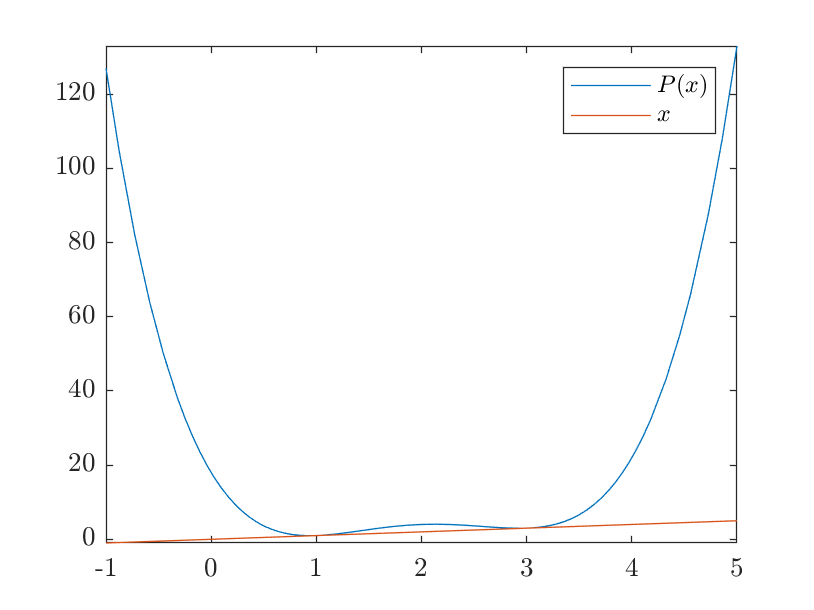

figure('Name', 'Toby''s Answer')
fplot(expressionHers, xinterval)
hold on;
fplot(x, xinterval)
legend({'$P(x)$', '$x$'})
hold off;

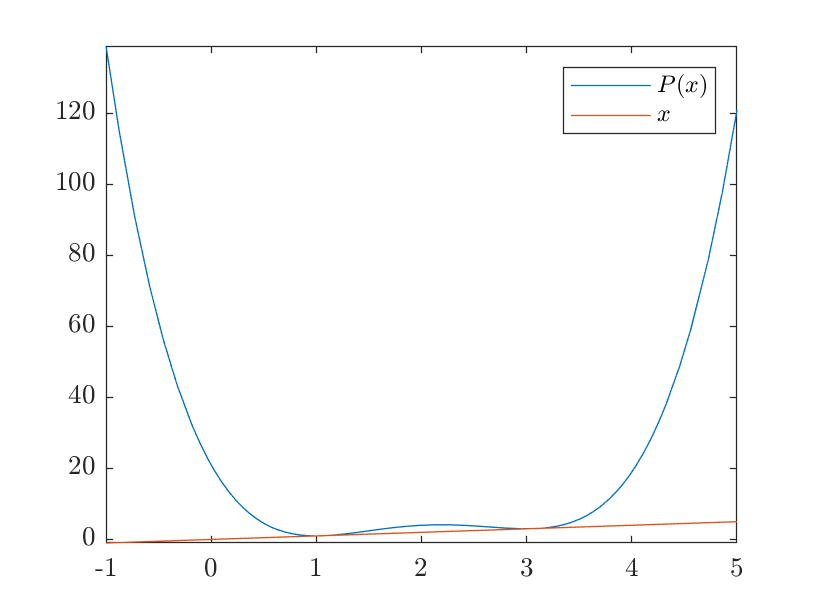


figure('Name', 'My Answer')
fplot(expressionMine, xinterval)
hold on;
fplot(x, xinterval)
legend({'$P(x)$', '$x$'})
hold off;